# Performance Evaluation of Battery Energy Storage System with Gridforming Control in MW Solar PV Park

This project evaluates the capabilities of a grid-forming (GFM) battery energy storage system (BESS) in maintaining a stable power system with high penetration of inverter-based solar photovoltaic (PV). 

Use this model to assess the dynamic performance of the BESS connected to PV plant during normal operation and contingencies, such as a large drop in PV power, significant load change, grid outage, and faults. Simulate the model to verify whether the designed PV plant and BESS unit, along with their associated controllers, conform the performance requirements the current IEEE 2800 standards recommend [1]. 

## Model Overview

This figure shows the top-level schematic of the simulation model. 

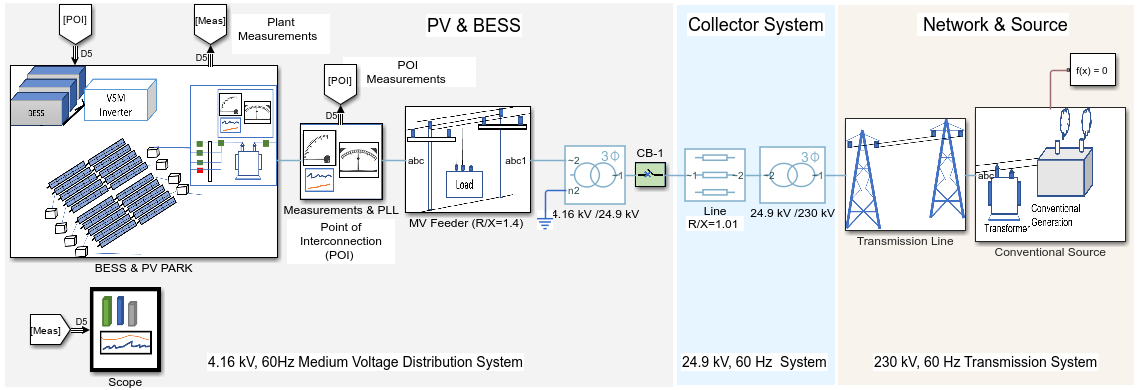       

The model comprises a PV plant and a BESS unit connected to the medium voltage (MV) network through a 4.16 kV/24.9 kV transformer. The PV plant inverters operate at their maximum power point (MPP) by using a phase locked loop (PLL)-based grid-following (GFL) control. The BESS inverter operates as a GFM unit, using a virtual synchronous-machine-based GFM controller [2]. You can find the details of the model in [Model Description.mlx](matlab:open('./BatteryStoragePVPlantGFMModelDescription.mlx')).                                                             

BatteryStoragePVPlantGFMParameters % Matlab script that loads the simulation parameters

## Performance Requirements from Inverter-based Resources (IBRs) According to IEEE 2800 Standard

### Ride Through Requirements 

Current standards, such as the IEEE 2800 [1], recommend all inverter-based plants to provide voltage and frequency disturbance ride-through capability. 

Any unwanted tripping of the inverter-based resource (IBR) plant, due to IBR plant self-protection, as a direct or indirect result of a voltage or frequency disturbance within a ride-through region, constitutes non-compliance with standard practice. The simulation in this model uses the voltage and frequency ride-through characteristics that the IEEE 2800 [1] standards recommend. During the ride-through period, the plant controller generates the reference current for the PV inverter.                         

This figure shows the voltage ride-through requirements for the IBR plants.        

TableI=readtable('BatteryStoragePVPlantGFMTRideThroughV.xlsx', ...
    'VariableNamingRule', 'preserve');

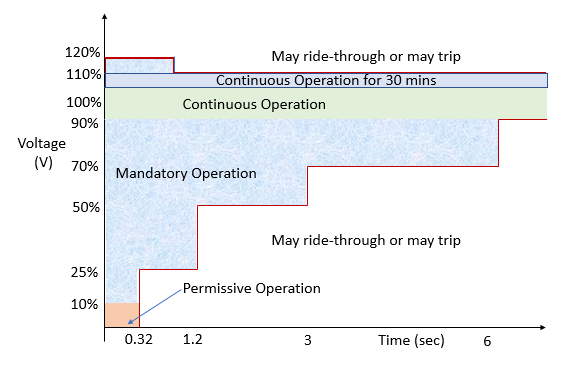

This figure and this table show the frequency ride-through requirements.

TableII=readtable('BatteryStoragePVPlantGFMTRideThroughF.xlsx', ...
    'VariableNamingRule', 'preserve');
TableII = table(TableII,'VariableNames',{'Table: Frequency Ride-through Requirements [1]'});
disp(TableII)

                               Table: Frequency Ride-through Requirements [1]                           
    Frequency Range    Percent from Nominal    Minimum Ride-through Time (s)         Operating Mode     
    ____________________________________________________________________________________________________

        {'f1'}                   3                          299                 {'Mandatory Operation' }
        {'f2'}                   2                          Inf                 {'Continuous Operation'}
        {'f3'}                  -2                          Inf                 {'Continuous Operation'}
        {'f4'}                  -5                          299                 {'Mandatory Operation' }



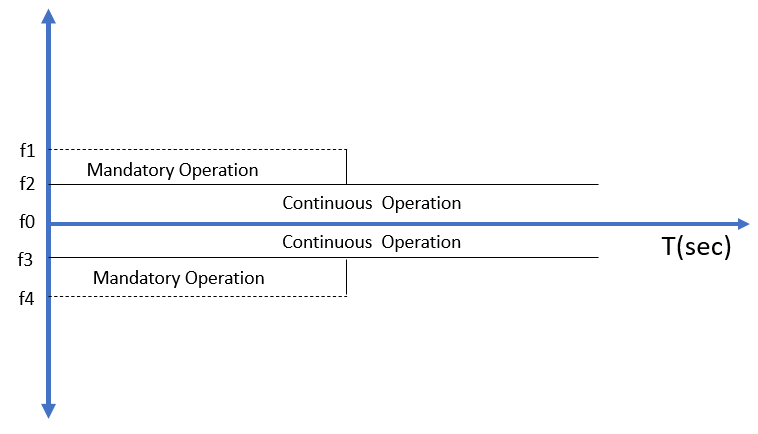   

The voltage and frequency ride-through characteristics are implemented in the PV plant controller by using lookup tables. The ride-through functions are activated by sensing the voltage magnitude at the point of interconnection (POI). This figure shows the implementation of ride-through functions.

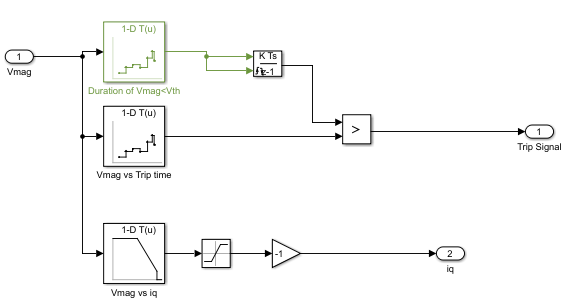 

## Configure Model to Run and Plot Results

### Simulation Settings

**Select Scenario: **In this study, you can simulate these scenarios:

- **Solar Power Variation **— Simulate a sudden reduction of PV power by curtailing the PV power output by 50%.

- **Large Load Change **— Simulate a sudden load change by increasing the load connected to 4.16 KV side of the plant transformer by 45%.                         

- **Grid Outage **— Simulate a grid outage condition by opening the circuit breaker, CB-1, which connects the plant transformer to MV network.

- **Temporary Fault **— Create a three-phase triple line fault (LLL fault) on the transmission line and cleared after 100 miliseconds. 

- **Permanent Fault **— Create a sustained three-phase LLL fault on the transmission line. 

The [`BatteryStoragePVPlantGFMSettingScenario.m`](matlab:open('./BatteryStoragePVPlantGFMSettingScenario.m')) function sets the parameters for a scenario you select. The function takes as input the scenario number from 1 to 5. To select any of the scenarios, set the `Scenario.number `variable`.` Similarly, to choose when to trigger the event, set the `Scenario.t_event` variable. To set the total simulation time, in seconds, use the `SimulationTime `variable.

#### **Select Grid Model**

This model provides two methods for modelling the grid (source). 

- The first method uses a frequency-controlled three-phase voltage source. 

- The second method uses a synchronous machine with governor and excitation control systems. 

The default method uses the frequency controlled three-phase voltage source. To select the second method use the variant subsystem.

%Default model is frequency controlled three-phase voltage source
GridModel=2; %Choose 1 for Synchronous machine and 2 for frequency controlled source
SynchronousMachine=Simulink.Variant(' GridModel == 1 ');
VSMFrequencyControlledSource =Simulink.Variant(' GridModel == 2 ');

#### **Select the Battery Controller**

This model provides two control modes for the BESS controller:

- The first control mode comprises a PLL-based GFL BESS controller with voltage and frequency support.

- The second control mode comprises a virtual synchronous machine (VSM) based grid-forming controller.

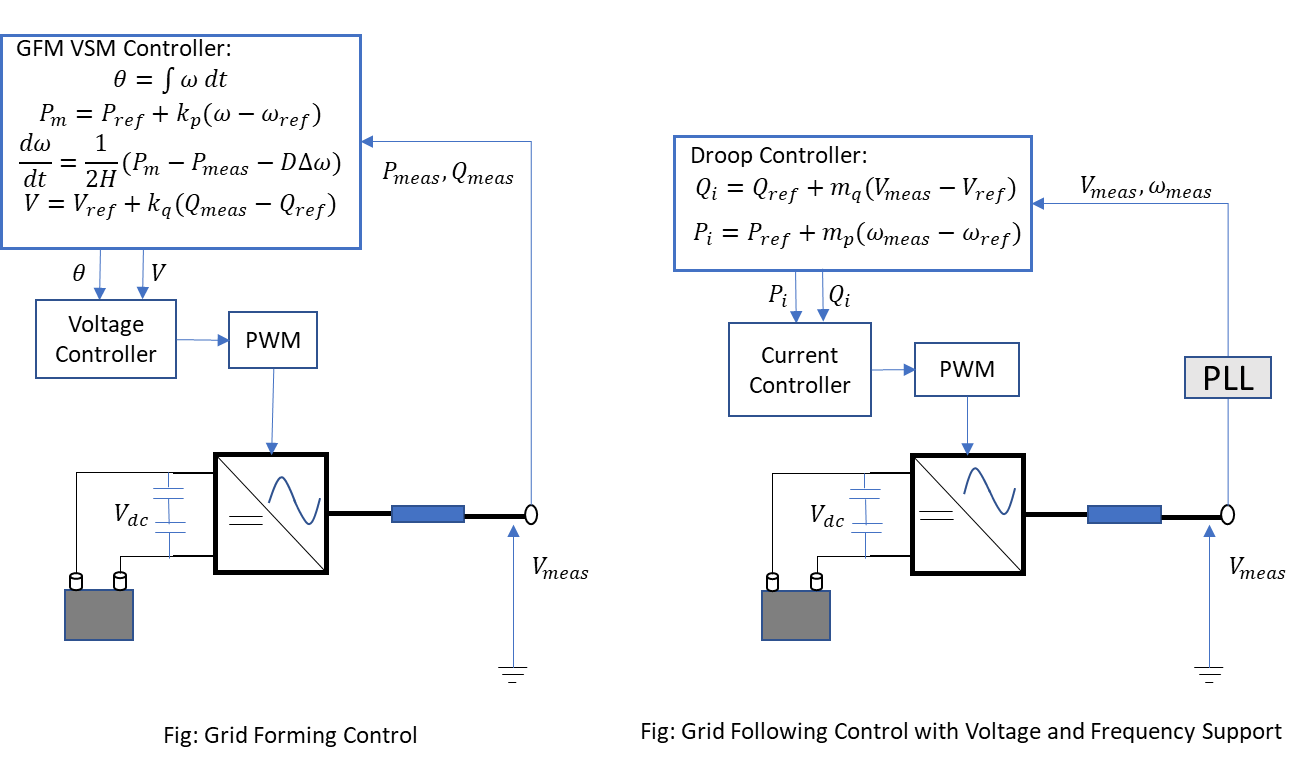

The default BESS controller is the GFM VSM controller.

%Default mode is VSM controller
BESSControl=1; %Choose Battery Controller, 1 for Grid forming VSM 
%, 2 for grid following with V&F support 
BESSVSMControl=Simulink.Variant(' BESSControl == 1 ');
BESSGridSupporting =Simulink.Variant(' BESSControl == 2 ');
if BESSControl==1
    Control='BESS Controller: Grid Forming VSM';
else
    Control='BESS Controller: Grid Following V & F Support';
end

## Simulation Results 

This section evaluates the BESS performance during various operating scenarios.

disp(Control)

BESS Controller: Grid Forming VSM


[SCRCal] = BatteryStoragePVPlantGFMSCRCal(Line,Feeder, ...
    Grid,SubTransmissionLine,PVpower); % Calculated short circuit ratio (SCR) at POI
disp(['Calculated SCR at POI: ',num2str(SCRCal.SCR)]);

Calculated SCR at POI: 0.43794


**Sudden Change in Solar Power **

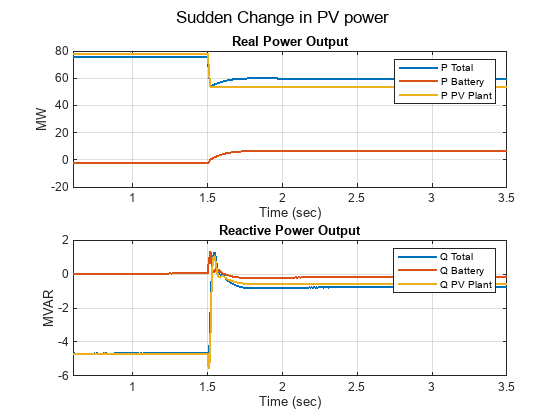

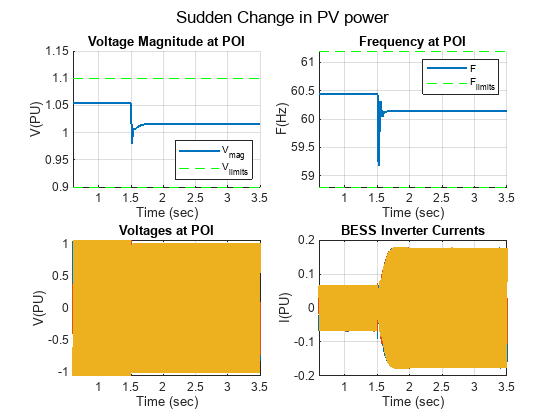

Scenario.number=1; % Sudden change in solar power 
Scenario.t_event=1.5; % Time at which the change occurs
BatteryStoragePVPlantGFMplot; % Matlab script that runs the model and plots the results

simlog2=logs_ee_spv_park_battery;

Observe the response of the BESS unit during a sudden drop in PV power output. From the simulation results you can see that the BESS with GFM control responds effectively during the disturbance, and it is able to provide the inertial power and the primary response  along with required reactive power to maintain stable system operation.

**Sudden Load Change**

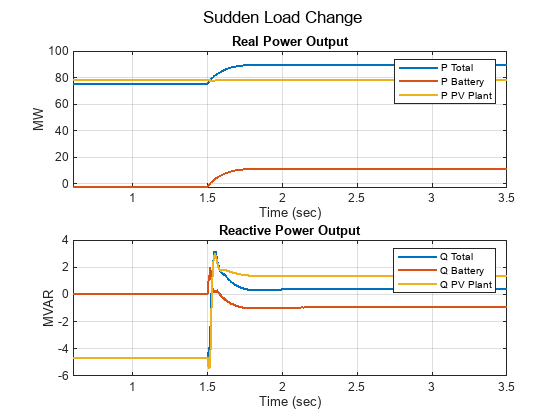

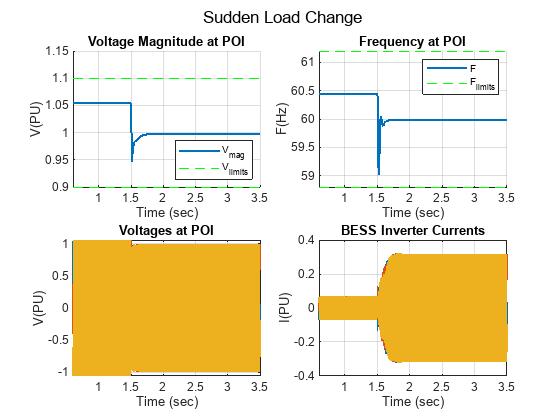

Scenario.number=2; %Sudden change in load
Scenario.t_event=1.5; % Time at which the change occurs
BatteryStoragePVPlantGFMplot; % Matlab script that runs the model and plots the results

Observe the response of the BESS unit during a sudden increase in the MV load. From the plots you can observe that the BESS with GFM control responded to the increase in load and was able to deliver the real and reactive powers required to maintain stable system operation.

**Grid Outage**

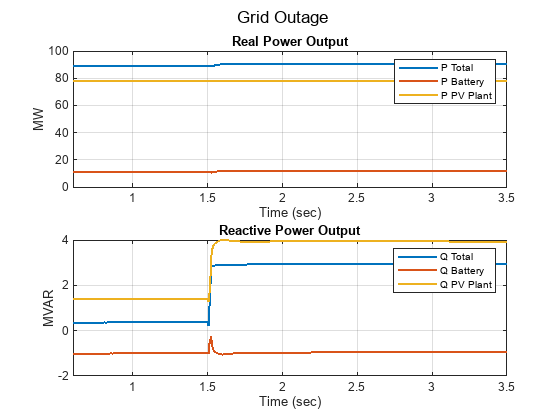

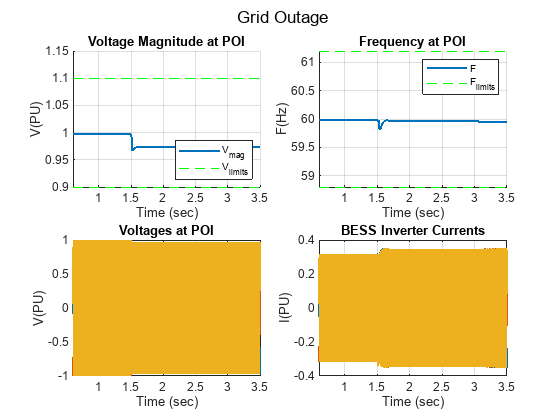

Scenario.number=3; % Grid outage
Scenario.t_event=1.5; % Time at which the change occurs
Load2CB_initial=0; %#ok<NASGU> % Lod initially disconnected
% connects the plant transformer to MV network, is open during grid outage.
BatteryStoragePVPlantGFMplot; % Matlab script that runs the model and plots the results

Observe the response of the BESS unit during a grid outage. From this simulation you can observe that the BESS with GFM control is able to deliver the power required by the MV load and can continue to run the MV network in islanded mode, with voltage and frequency within the acceptable limits that the IEEE standards recommended.

**Temporary Fault**

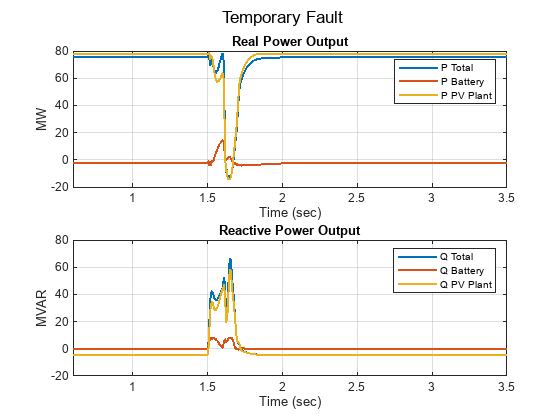

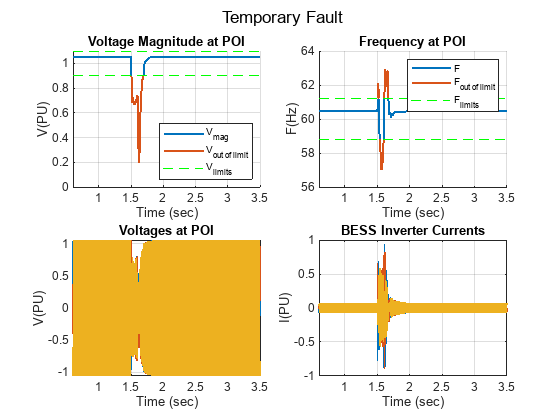

Scenario.number=4; % Temporary fault
Scenario.t_event=1.5; % Time at which the fault occurs
% A 3-phase triple line fault (LLL-fault) is created on the transmission line 
% and cleared after 100 ms. 
Load2CB_initial=1; % Load initially disconnected
BatteryStoragePVPlantGFMplot; % Matlab script that runs the model and plots the results

Observe the response of the BESS unit during a three-phase (LLL) fault occuring at the transmission line at 1.5 seconds. The fault is cleared after 100ms. From the simulation results you can observe that the PV and BESS units are able to ride-through low voltage and frequency variation during the fault, which is in compliance with the ride-through requirements in IEEE 2800 standards. Once the fault is cleared, the system returns to its pre-fault state within 0.5 sec, which is also in compliance with the post-fault recovery requirements set by IEEE 2800 standard. 

**Permanent Fault**

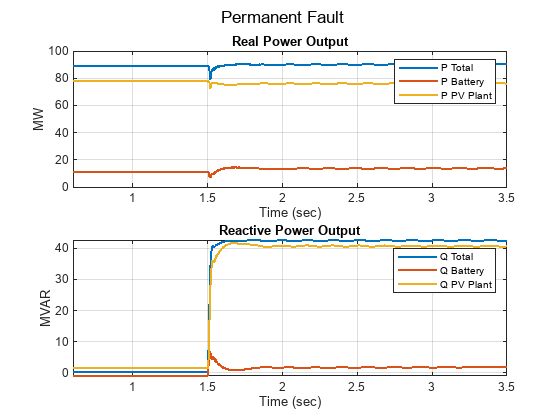

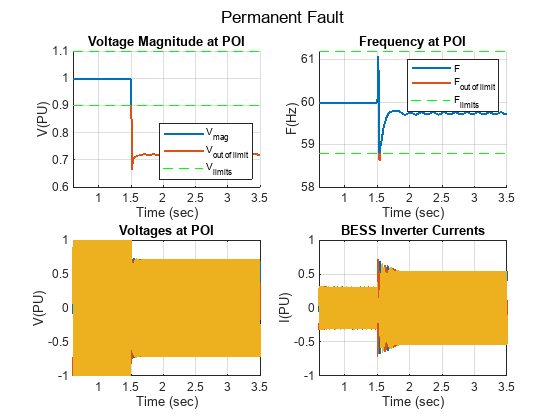

Scenario.number=5; %Permanent fault
Scenario.t_event=1.5; % Time at which the fault occurs
% A sustained 3-phase triple line fault (LLL- fault) is created on the transmission line. 
Load2CB_initial=0; % Load initially disconnected
BatteryStoragePVPlantGFMplot; % Matlab script that runs the model and plots the results

Observe the response of the BESS unit during a permanent three-phase to ground fault occuring at the transmission line at 1.5 seconds. From the simulation results you can observe that the PV and BESS units are able to ride-through low valtage and frequency variation during the fault for the duration mentioned in the IEEE standards. However, as the fault is not cleared and voltages do not recover within the time limit set by the ride-through requirements, the plant central controller trips the PV plant and BESS unit for such a permanent fault.

## Design Evaluation: Compliance with IEEE 2800 Standard 

Design evaluation (offline study) is an engineering evaluation to verify that the renewable plant or the IBR unit(s) meets the interconnection and interoperability requirements that the standard specifies. The IBR owner, the system operator, or other third parties perform the design evaluation. Design evaluation generally requires modeling and simulation of the IBR plants to capture their interactions with the power transmission system.

You can evaluate whether the designed BESS and PV plant complies with the performance criteria that the IEEE 2800 standards recommends. This table shows the list of the design critera on which the performance of the simulated PV and BESS units is tested.

disp(TableIII)

                                  Table: Compliance with IEEE 2800 Standards [1]                              
                   Requirements                                 Recommendations [1]                  Satisfied
    __________________________________________________________________________________________________________

    {'Reactive Power Capability'             }    {'Q (minimum) as percentage of rated power'   }     {'✓'}  
    {'Voltage & Recative Power Control Modes'}    {'Reactive power droop control'               }     {'✓'}  
    {'Primary Frequency Response'            }    {'Provide frequency response'                 }     {'✓'}  
    {'Voltage Disturbance Ride-hrough'       }    {'Low voltage & high voltage ride through'    }     {'✓'}  
    {'Frerquency Ride-through'               }    {'Low frequency & high frequency ride through'}     {'✓'}  



## Evaluation of BESS Response with GFM and GFL Control for Varying Grid Strength

In this section you can evaluate the BESS reponse with GFM and GFL controllers under varying levels of grid strength.

### Grid Strength Evaluation

This example uses short circuit ratio (SCR) as the metric to assess the system strength at point of interconnection (POI) of renewable plant [1]. 

- SCR is defined as the ratio between the three-phase short circuit MVA at a location to the MW rating of the source connected at that location. 


$$\textrm{SCR}=\frac{\textrm{Shot}\;\textrm{circuit}\;\textrm{MVA}\;\textrm{at}\;\textrm{POI}}{\textrm{MW}\;\textrm{of}\;\textrm{renewable}\;\textrm{power}\;\textrm{injected}\;\textrm{at}\;\textrm{POI}}$$


- A low SCR might indicate a weak grid scenario, where the renewable source has the ability to significantly change the voltages at the POI.

However, for a grid dominated with inverter-based renewable (IBR) sources, the chances of an unstable operation of an IBR plant depend on these factors:

- Short circuit strength at the POI

- Active power output of the renewable 

- Tuning of inverter controllers  

- Voltage and reactive power control 

- Interaction with nearby IBR plants 

The [`BatteryStoragePVPlantGFMSCRCal`](matlab:open('./BatteryStoragePVPlantGFMSCRCal.m')) function calculates the SCR at the POI for a given network parameters. The [`BatteryStoragePVPlantGFMComparisonGFLvsGFM`](matlab:open('./BatteryStoragePVPlantGFMComparisonGFLvsGFM.m')) script runs the simulations and plots the results for the comparative assessment. The SCR at the POI varies by changing the feeder length and total PV output power.

BESS Controller: Grid Following V & F Support
Calculated SCR at POI: 2.0507


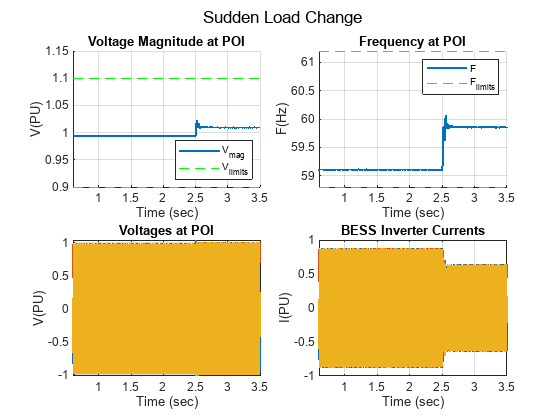

BESS Controller: Grid Following V & F Support
Calculated SCR at POI: 0.43794


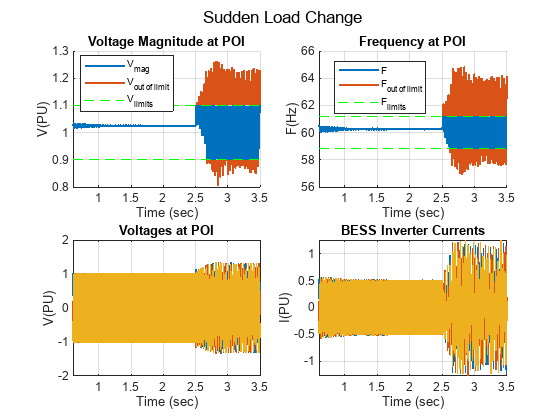

BESS Controller: Grid Forming VSM


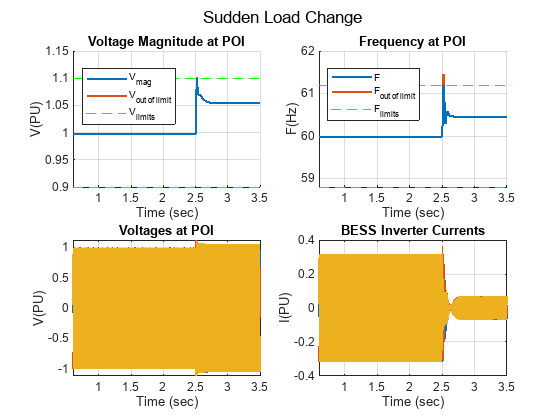

BatteryStoragePVPlantGFMComparisonGFLvsGFM; % Matlab script that runs the model and plots the results

close(h1_simlog_ee_spv_park_battery_voltage_currents); % Colse Figure
close(h1_simlog_ee_spv_park_battery); % Close Figure

TableIV=readtable('GFMvsGFLwithSCR.xlsx', ...
    'VariableNamingRule', 'preserve');
TableIV = table(TableIV,'VariableNames',{'Table:GFM vs GFL BESS Control with Varying SCR'});
TableIV.(1)(1,1).('Grid Strength (SCR)')=SCRCal1.SCR;
TableIV.(1)(2,1).('Grid Strength (SCR)')=SCRCal1.SCR;
TableIV.(1)(3,1).('Grid Strength (SCR)')=SCRCal3.SCR;
TableIV.(1)(4,1).('Grid Strength (SCR)')=SCRCal3.SCR;
disp(TableIV);

          Table:GFM vs GFL BESS Control with Varying SCR       
    Grid Strength (SCR)          Control              Status   
    ___________________________________________________________

           2.0507          {'Grid Following'  }    {'Stable'  }
           2.0507          {'Grid Forming VSM'}    {'Stable'  }
          0.43794          {'Grid Following'  }    {'Unstable'}
          0.43794          {'Grid Forming VSM'}    {'Stable'  }



From these plots you can observe that after a disturbance in an weak grid (SCR<1), the GFL BESS controller is unable to maintain stable voltages at POI, while the GFM BESS controller is stable. This table summarizes the observations made for varying the grid strength.

## References

[1] [IEEE 2800 Standard for Interconnection and Interoperability of Inverter-Based Resources (IBRs) Interconnecting with Associated Transmission Electric Power Systems](https://standards.ieee.org/ieee/2800/10453/).

[2] [GC0137: Minimum Specification Required for Provision of GB Grid Forming (GBGF) Capability (formerly Virtual Synchronous Machine/VSM Capability)](https://www.nationalgrideso.com/industry-information/codes/grid-code-old/modifications/gc0137-minimum-specification-required).

Copyright 2022 - 2023 The MathWorks, Inc.